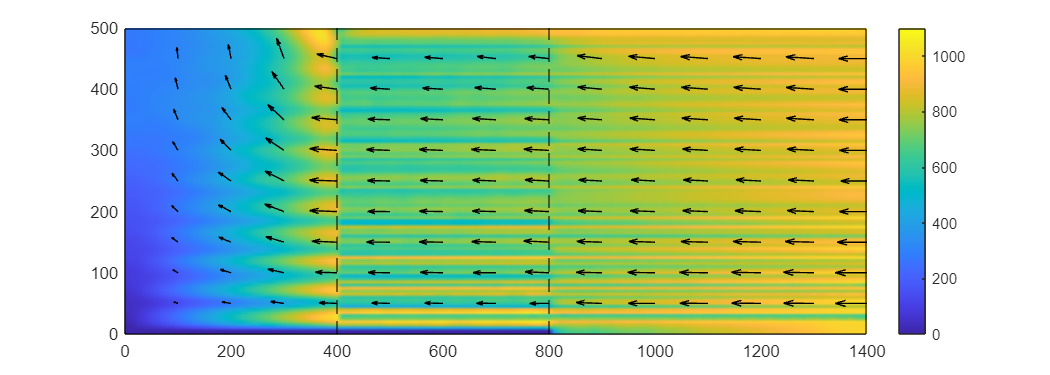

L = 1400*1e-9;
R = 500*1e-9;
L1 = 400/1400;
L2 = 800/1400;

x = linspace(0, L, 141);
y = linspace(0, R, 101);
U = 1000*1e-9;
[X, Y] = meshgrid(x, y);

xlim([0, 1400])
ylim([0, 500])
hold on
magnitude_comsol = 1e9*sqrt(axial_flux_comsol.^2 + radial_flux_comsol.^2);
im1 = imagesc(1e9*[x(1), x(end)], 1e9*[y(1), y(end)], magnitude_comsol);
im1.Interpolation = 'bilinear';
hold on
xline(1e9*L1*L, '--k', 'LineWidth', 1)
xline(1e9*L2*L, '--k', 'LineWidth', 1)
xlim([0, 1e9*L])
x0=10;
y0=10;
width=300*(L/R);
height=300;
set(gcf,'position',[x0,y0,width,height])
xline(0, 'k')
xline(1400, 'k')
yline(0, 'k')
yline(500, 'k')
colorbar
clim([0, 1100])
temp1 = linspace(1, length(y), 11);
temp1 = floor(temp1(2:(end-1)));
temp2 = linspace(1, length(x), 15);
temp2 = floor(temp2(2:(end)));
quiver(1e9*X(temp1, temp2), 1e9*Y(temp1, temp2), 6*1e7*axial_flux_comsol(temp1, temp2), 6*1e7*radial_flux_comsol(temp1, temp2), 'off', 'k')
hold off